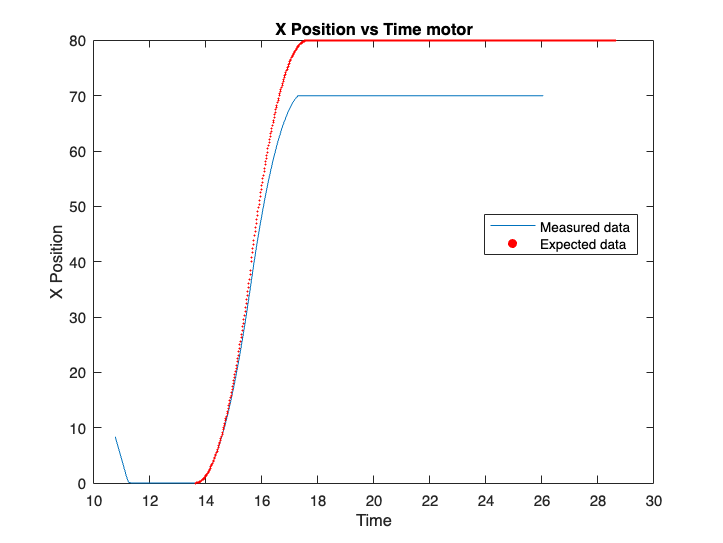

freq = 50;

% Define the file name
crane_file = 'crane_poly_abrupt_06_90.csv';
input_data_pos = csvread(".csv");
input_data_vel = csvread("input_poly_velocity_abrupt_06_90.csv");

% Read the CSV file
data = csvread(crane_file, 10000); % Skip the first 6000 rows

% Extract time (1st column) and x position (4th column)
time =  data(:,1);
x_position = data(:, 4);
x_velocity = data(:,5);
angle = data(:, 15);
y_position = data(:,6);
last_zero_index = find(x_position == 0, 1, 'last');
time_shift = time(last_zero_index);



input_time = 1:length(input_data_pos);
input_position = input_data_pos(1,:);

input_velocity = input_data_vel(1,:);


figure;
plot(time, x_position);
xlabel('Time');
ylabel('X Position');
hold on 
scatter(input_time/freq + time_shift, input_position*100, 2, 'r', 'filled');
hold off
title('X Position vs Time motor');
legend('Measured data', 'Expected data', 'Location', 'best');

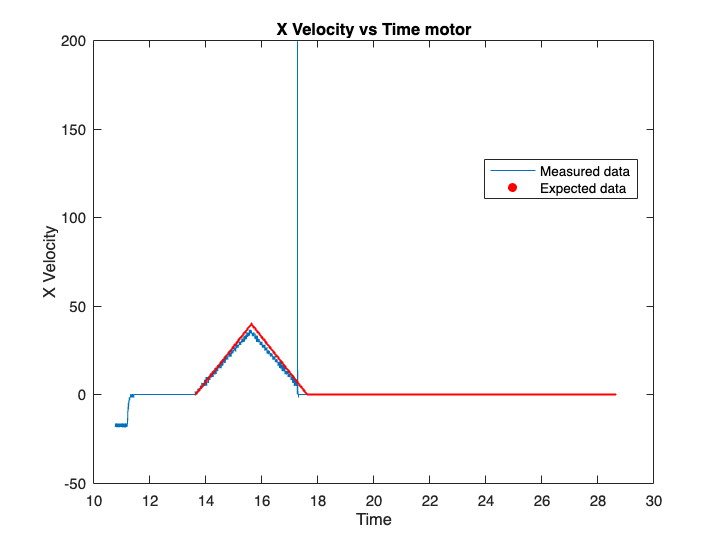



figure;
plot(time, x_velocity);
xlabel('Time');
ylabel('X Velocity');
hold on 
scatter(input_time/freq + time_shift, input_velocity*100, 2, 'r', 'filled');
hold off
title('X Velocity vs Time motor');
legend('Measured data', 'Expected data', 'Location', 'best');

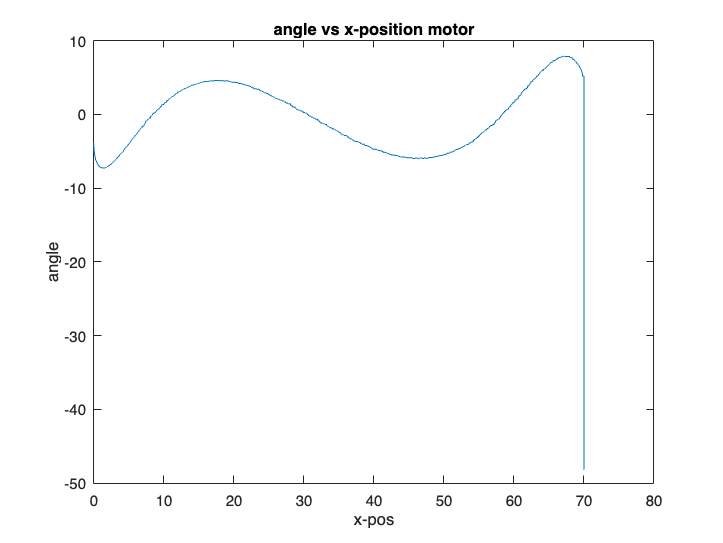




figure
plot(x_position(last_zero_index:end), angle(last_zero_index:end));
xlabel('x-pos');
ylabel('angle');
title('angle vs x-position motor');

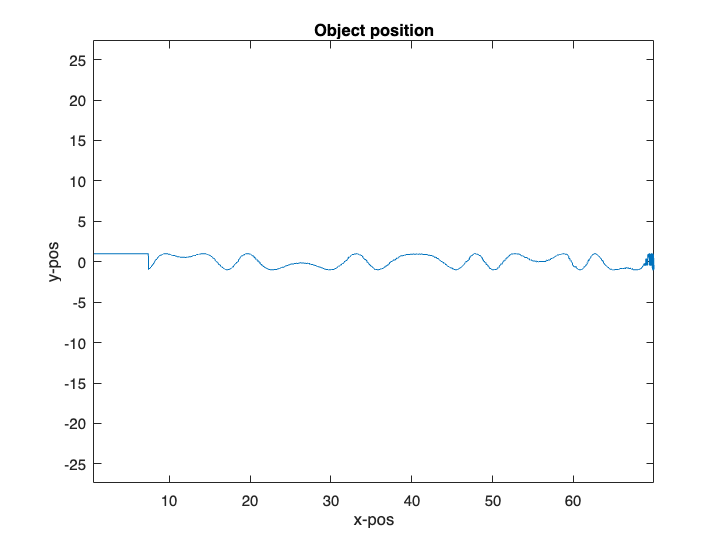



figure
plot(smoothdata(x_position +sin(angle)), cos(angle));
xlabel('x-pos');
ylabel('y-pos');
title('Object position');
axis equal